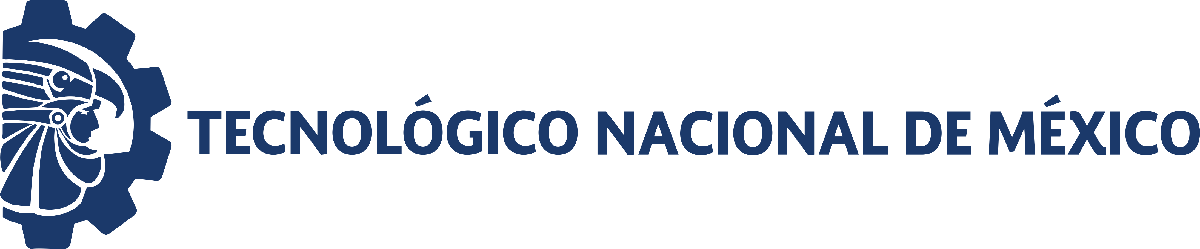                                 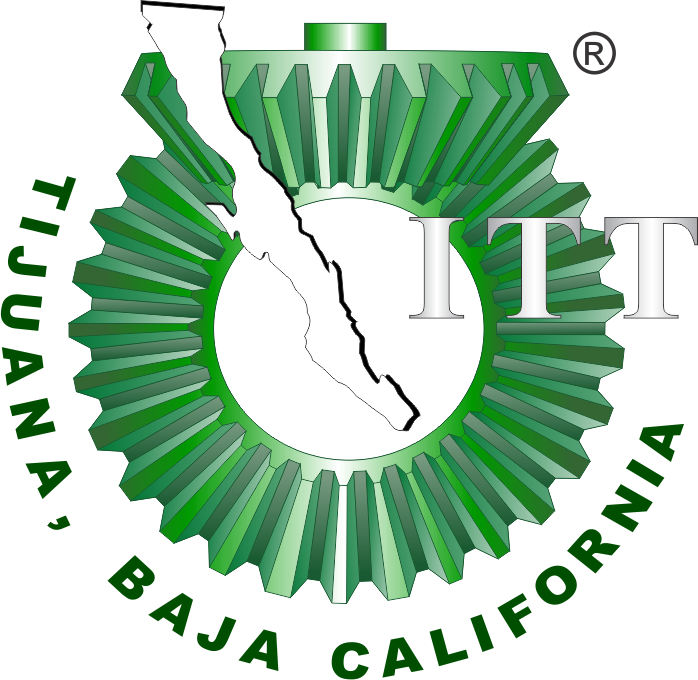

# Práctica dos: Sistema respiratorio

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

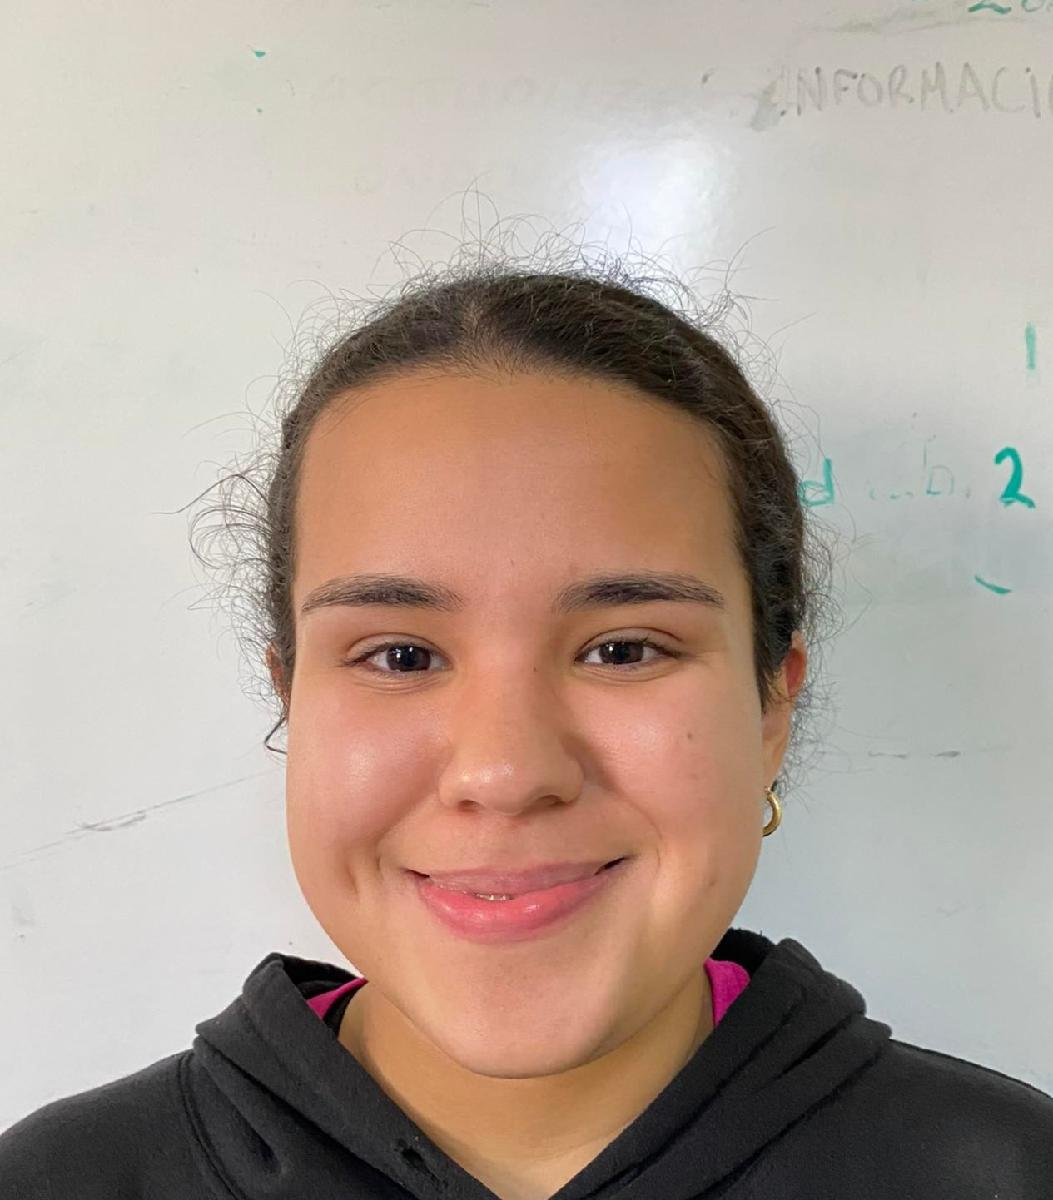

Nombre del alumno: **Mariana Rivera Peñuelas** 

Número de control: **22210427**

Correo institucional: **l22210427@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Rivera22210427P2';
open_system(file);
tend = '30';
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Rendimiento del controlador

kP= '200.5238'

kP = '200.5238'

kI= '3760.859'

kI = '3760.859'

kD= '1.001'

kD = '1.001'

Settlingtime = '0.0985'

Settlingtime = '0.0985'

Overshoot= '7.19'

Overshoot = '7.19'

Peak= '1.07'

Peak = '1.07'

## Respiración normal

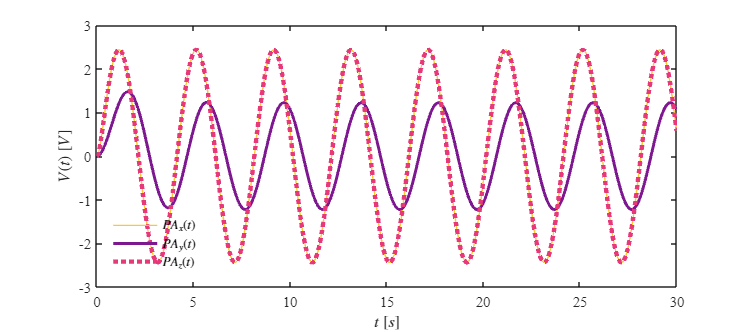

Signal = 'Respiracion normal';
set_param('Rivera22210427P2/Pao(t)', 'sw', '1');
set_param('Rivera22210427P2/PID Controller', 'P', '200.5238');
set_param('Rivera22210427P2/PID Controller', 'I', '3760.859');
set_param('Rivera22210427P2/PID Controller', 'D', '1.001');
N = sim(file, parameters);
plotsignals(N.t, N.PAx, N.PAy, N.PAz, Signal)

## Respiración anormal

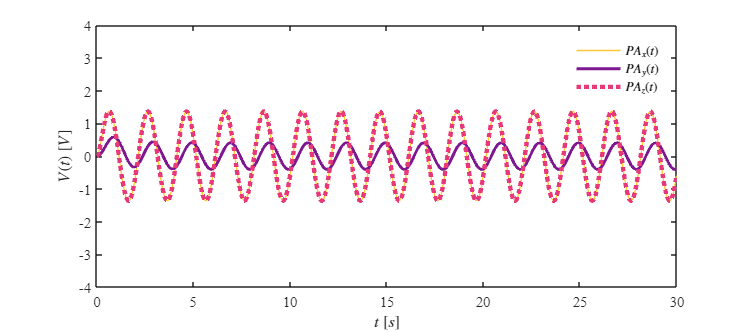

Signal = 'Respiracion anormal';
set_param('Rivera22210427P2/Pao(t)', 'sw', '0');
set_param('Rivera22210427P2/PID Controller', 'P', '200.5238');
set_param('Rivera22210427P2/PID Controller', 'I', '3760.859');
set_param('Rivera22210427P2/PID Controller', 'D', '1.001');
N2 = sim(file, parameters);
plotsignals(N2.t, N2.PAx, N2.PAy, N2.PAz, Signal)

## Función: Respuestas a las señales

function plotsignals(t, PAx, PAy, PAz, Signal)
    set(figure(), 'Color', 'w')
    set(gcf, 'units', 'Centimeters', 'Position', [1,1,18,8])
    set(gca, 'FontName', 'Times New Roman')
    fontsize(10, 'points')
    AMARILLO = [252/255, 199/255, 55/255];
    MORADO = [126/255, 24/255, 145/255];
    ROSA = [231/255, 56/255, 121/255];
    hold on; grid off; box on

    plot(t,PAx,'LineWidth',1, 'Color', AMARILLO)
    plot(t,PAy,'LineWidth',2,'Color', MORADO)
    plot(t,PAz,':','LineWidth',3,'Color', ROSA)

    xlabel('$t$ $[s]$', 'Interpreter', 'Latex')
    ylabel('$V(t)$ $[V]$', 'Interpreter', 'Latex')


    L = legend('$PA_{x}(t)$', '$PA_{y}(t)$', '$PA_{z}(t)$');
    set(L, 'Interpreter', 'Latex', 'Location', 'Best', 'Box', 'Off')

    if Signal == "Respitacion normal"
        xlim([0, 30]); 
        ylim([-4, 4]); 

    elseif Signal == "Respiracion anormal"
        xlim([0, 30]); 
        ylim([-4, 4]);
    
    end
    exportgraphics(gcf, [Signal, '.pdf'], 'ContentType', 'Vector')

end